# Lab 9 Radio Havana

### ### Agam Goyal ###

## Item 0: Load Workspace 

close all
clear

load short_wave.mat

N = length(x_IQ);

## Item 1: Plot Spectrum of Down-converted Signal

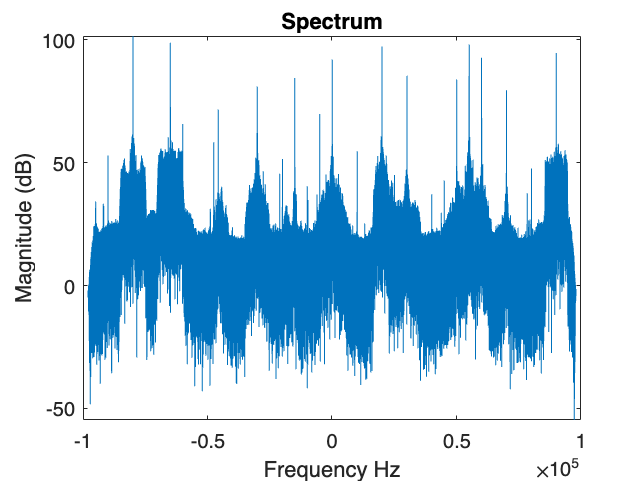

X_IQ = abs(fftshift(fft(x_IQ)));

freq_x = [-(N-1)/2:(N-1)/2] * Fs/N; % DFT frequencies in continous time

plot(freq_x, 20*log10(X_IQ))
xlabel('Frequency Hz')  % <-- Axis label
ylabel('Magnitude (dB)') % <-- Axis label
title('Spectrum') % <-- graph title

## Item 3: Find DFT indices for the Carrier Frequency and Tolerance

% find exact carrier frequency
fc = 90000; % Hz
tol = 50; % Hz

% Calculate ind_c and ind_tol in terms of fc and tol 
ind_c = round((N+1)/2 + ((fc/Fs)*N));  % <-- Index corresponding to fc (integer)
ind_tol = ceil(tol/(freq_x(2)-freq_x(1)));  % <-- Index corresponding to tol (integer)

ind_i = getPeak(X_IQ, ind_c, ind_tol);
f_i = freq_x(ind_i);  %frequency corresponding to peak index

## Item 4: Demodulate Radio Havana

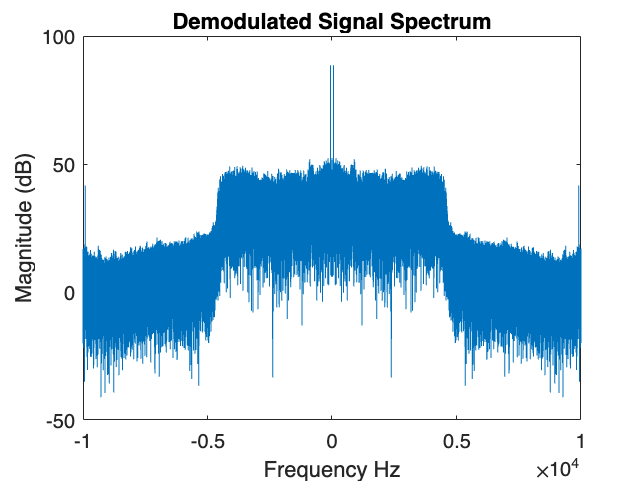

% Demodulate message to account for inexact carrier frequency

s = exp(-j*2*pi*f_i*[0:N-1]/Fs); % <--- complex sinusoid corresponding to exact carrier
x_b = real(x_IQ.*s);

a = filter(h,1,x_b);  % <--- apply lowpass filter

% Play demodulated signal
% soundsc(a,Fs)

X_b = abs(fftshift(fft(x_b)));
% Plot Demodulated Signal Spectrum
figure
plot(freq_x, 20*log10(X_b));
xlabel('Frequency Hz')
ylabel('Magnitude (dB)')
title('Demodulated Signal Spectrum')
xlim([-10000,10000])

## Item 5: Plot Frequency Response of Final Low Pass Filter

**Note**: The following plot will be used for the corresponding Lab Assignment

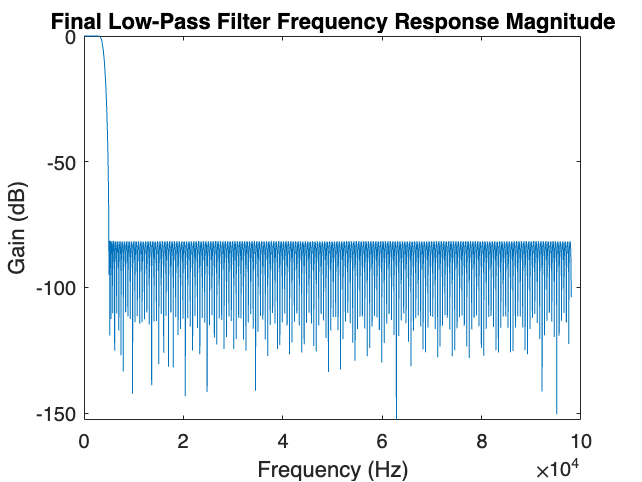

[H,freq_h] = freqz(h,1,8192,Fs);

figure
plot(freq_h,20*log10(abs(H)))
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Final Low-Pass Filter Frequency Response Magnitude')